# **Chronic Myeloid Leukemia: Patient survival prediction.**

**A cancer patient data set containing 97 patient samples and approx 22k genes or features will be used to train a model to predict patient survival into three possible classes: alive, alive_relapse, relapse_dead.**

%load Data
newData = readtable('CNV_log2_trans_out.csv','ReadRowNames',true,'PreserveVariableNames',true);
save('newData.mat', 'newData');

load('newData.mat');
[d,t1] = xlsread('clinical_labels.xlsx');
response = categorical(d(:,6));
newData.class = response;
feature_table = newData;


rng(1)
% Use 70% of data for training and remaining for testing
split_training_testing = cvpartition(feature_table.class, 'Holdout', 0.3);
% Dummyvar
newData.class = dummyvar(newData.class);
% Create a training set
training_set = feature_table(split_training_testing.training, :);

% Create a validation set
testing_set = feature_table(split_training_testing.test, :);

grpstats_training = grpstats(training_set, 'class', 'mean');
disp(grpstats_training(:,'GroupCount'))

          GroupCount
          __________

    0         22    
    10        19    
    11        27    




% Create a random sub sample (to speed up training) from the training set
subsample = [1:height(training_set)];

% Create a 10-fold cross-validation set from training data
cvp = cvpartition(length(subsample),'KFold',15);

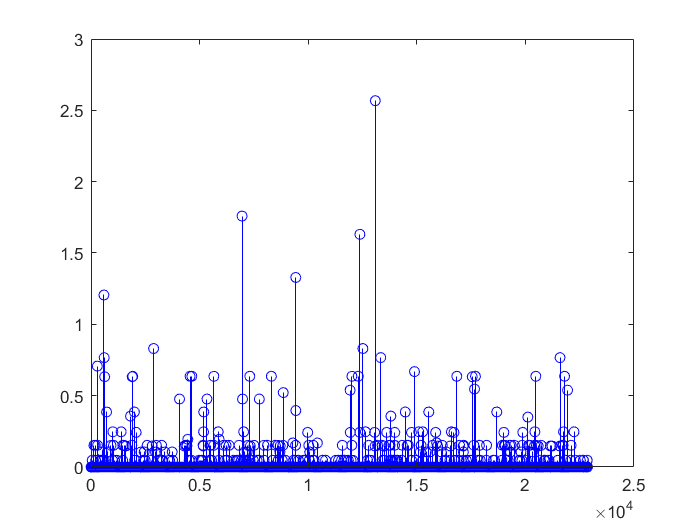

% Perform feature selection with neighborhood component feature selection
rng(1)
mdl = fscnca(table2array(training_set(:,1:(length(feature_table.Properties.VariableNames)-1))), ...
    table2array(training_set(:,length(feature_table.Properties.VariableNames))), 'Lambda', 0.005, 'Verbose', 0);

% Select features with weight above 1
selected_feature_indx = find(mdl.FeatureWeights > 0.1);

% Plot feature weights
stem(mdl.FeatureWeights,'bo');


% Load saved array of selected feature indexes to ensure reproducibility
%load('SelectedFeatures.mat')

% Display list of selected features
disp(feature_table.Properties.VariableNames(selected_feature_indx))

  Columns 1 through 8

    'ACAD8'    'ACRV1'    'ADAM6'    'ADAMTS15'    'ADAMTS8'    'AIP'    'ALDH3B2'    'ALG11'

  Columns 9 through 15

    'ALKBH3'    'ALKBH3_AS1'    'ANGPTL6'    'ANKRD13D'    'APLP2'    'ARG2'    'ARHGAP32'

  Columns 16 through 22

    'ATP6V1D'    'B3GAT1'    'BARX2'    'BCORP1'    'BTBD6'    'C11orf44'    'C11orf45'

  Columns 23 through 29

    'C11orf96'    'C13orf42'    'C19orf66'    'C20orf204'    'CABP2'    'CABP4'    'CARNS1'

  Columns 30 through 37

    'CCDC15'    'CD24'    'CDADC1'    'CDK2AP2'    'CDON'    'CHEK1'    'CLCF1'    'CORO1B'

  Columns 38 through 45

    'CTSS'    'DAZ1'    'DAZ2'    'DCPS'    'DDX25'    'DDX3Y'    'DEFB107A'    'DEFB107B'

  Columns 46 through 53

    'DHRS12'    'DLEU7'    'DLEU7_AS1'    'EI24'    'EIF1AY'    'EIF2S1'    'EIF3G'    'ENSA'

  Columns 54 through 60

    'ESAM'    'ETS1'    'FAM118B'    'FAM124A'    'FAM71D'    'FAM90A10P'    'FAM90A7P'

  Columns 61 through 67

    'FEZ1'    'FLI1'    'FOXRED1'    'GL

cnv_sel_features_weight=mdl.FeatureWeights(selected_feature_indx)

cnv_sel_features_weight =     0.1521
    0.1521
    0.7074
    0.1521
    0.1521
    0.1054
    1.2058
    0.7667
    0.6329
    0.6329


cnv_sel_features =feature_table.Properties.VariableNames(selected_feature_indx)

cnv_sel_features = 1×211 cell array
    {'ACAD8'}    {'ACRV1'}    {'ADAM6'}    {'ADAMTS15'}    {'ADAMTS8'}    {'AIP'}    {'ALDH3B2'}    {'ALG11'}    {'ALKBH3'}    {'ALKBH3_AS1'}    {'ANGPTL6'}    {'ANKRD13D'}    {'APLP2'}    {'ARG2'}    {'ARHGAP32'}    {'ATP6V1D'}    {'B3GAT1'}    {'BARX2'}    {'BCORP1'}    {'BTBD6'}    {'C11orf44'}    {'C11orf45'}    {'C11orf96'}    {'C13orf42'}    {'C19orf66'}    {'C20orf204'}    {'CABP2'}    {'CABP4'}    {'CARNS1'}    {'CCDC15'}    {'CD24'}    {'CDADC1'}    {'CDK2AP2'}    {'CDON'}    {'CHEK1'}    {'CLCF1'}    {'CORO1B'}    {'CTSS'}    {'DAZ1'}    {'DAZ2'}    {'DCPS'}    {'DDX25'}    {'DDX3Y'}    {'DEFB107A'}    {'DEFB107B'}    {'DHRS12'}    {'DLEU7'}    {'DLEU7_AS1'}    {'EI24'}    {'EIF1AY'}    {'EIF2S1'}    {'EIF3G'}    {'ENSA'}    {'ESAM'}    {'ETS1'}    {'FAM118B'}    {'FAM124A'}    {'FAM71D'}    {'FAM90A10P'}    {'FAM90A7P'}    {'FEZ1'}    {'FLI1'}    {'FOXRED1'}    {'GLB1L2'}    {'GLB1L3'}    {'GOLGA6L1'}    {'GOLGA8DP'}    {'GOLPH3L'}    {'GP

%final_table = (table2array(feature_table(:,selected_feature_indx)))';
final_table = feature_table(:,selected_feature_indx);
writetable( final_table,'./NCA_Outputs/cnv_sel_features_211genes.xlsx', 'WriteRowNames',true);
%csvwrite('./NCA_outputs/mutation_selected_features.csv', mutation_sel_features)

cnvfeatweight= mdl.FeatureWeights(selected_feature_indx);
cnvfeatweight_tab= table(cnvfeatweight);
cnv_sel_features =feature_table.Properties.VariableNames(selected_feature_indx)';
%cnv_sel_features_tab= cell2table(cnv_sel_features);
Selected_features= table(cnv_sel_features,cnvfeatweight);   
writetable( Selected_features,'./NCA_Outputs/cnv_sel_features_weights.xlsx', 'WriteRowNames',true);

d2 = d(:,[1:5])';
T = newData.class;
resp_table= table(T);
writetable(resp_table, './NCA_Outputs/response.xlsx');


final_clinical_table = table(d2');
writetable(final_clinical_table, './NCA_Outputs/Clin_feat_for_NN.xlsx','WriteRowNames',true);

rowNames = newData.Properties.RowNames;
clin_feat ={'Age','Gender','OS_Time (Overall Survival)','Chemotherapy Regimen 1','ISS'};

%neural network for pattern recognition


P = (table2array(feature_table(:,selected_feature_indx)))';

final_table = table(P',d2');


P1 = (table2array(final_table))';

T = newData.class';

% % === train the network
% [net,tr] = train(net,P,T)
x = P1;
t = T;

# Code 2: 10 fold cross validation neural net model

rng(1);
k = 10;
%cvFolds = 1+mod(randperm(N),k);
%cvFolds =  crossvalind('Kfold', response, k)
cv = cvpartition(response,'KFold',10)

cv = K-fold cross validation partition
   NumObservations: 97
       NumTestSets: 10
         TrainSize: 88  87  87  87  87  87  87  87  88  88
          TestSize: 9  10  10  10  10  10  10  10   9   9

ans =      1     2     4     5     6     7     8     9    10    11    12    14    15    16    17    18    19    20    21    22    23    25    26    27    28    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    47    48    49    50    51    52    53    54    55


ans =     82    83    84    85    86    87    88    89    90    91    94    95    96    97


ans =      3    13    24    29    46    68    74    92    93


performance = 0.0909

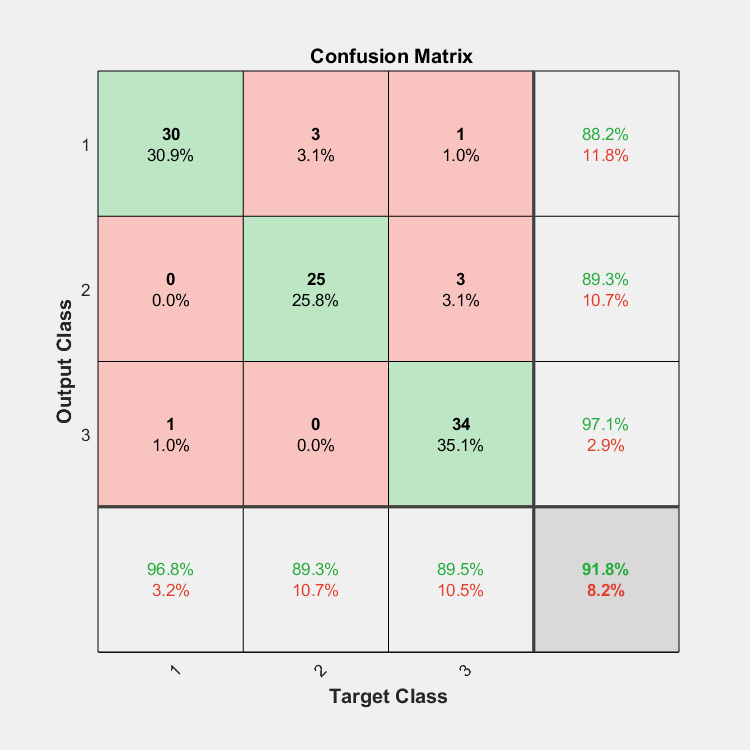

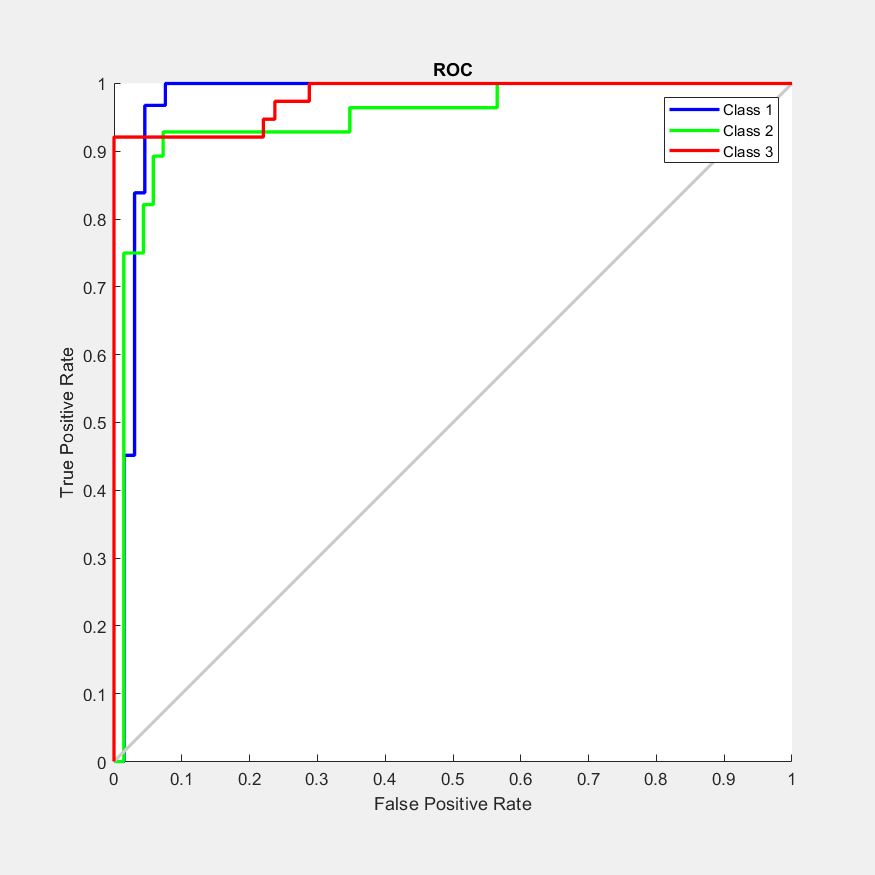

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    16    17    18    19    20    21    22    23    24    26    27    28    29    30    31    32    33    35    36    37    38    40    41    42    43    44    45    46    47    48    50    51    52    53    56    57


ans =     84    85    86    87    89    90    91    92    93    94    95    96    97


ans =     15    25    34    39    49    54    55    59    63    88


performance = 0.0909

ans =      1     2     3     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    52    53


ans =     83    84    87    88    89    90    91    92    93    94    95    96    97


ans =      4    28    51    56    66    70    80    82    85    86


performance = 0.0909

ans =      1     2     3     4     5     6     7     8     9    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    32    33    34    35    37    38    39    40    41    42    44    45    46    48    49    50    51    52    53    54    55


ans =     83    84    85    86    87    88    91    92    93    94    95    96    97


ans =     10    31    36    43    47    65    72    79    89    90


performance = 0.0909

ans =      1     2     3     4     5     6     7     8     9    10    11    13    14    15    16    17    19    20    21    22    23    24    25    26    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    49    50    51    52    53    54


ans =     85    86    87    88    89    90    91    92    93    94    95    96    97


ans =     12    18    27    48    61    67    73    77    78    83


performance = 0.0909

ans =      1     2     3     4     5     7     8    10    11    12    13    14    15    16    17    18    19    20    21    22    24    25    26    27    28    29    31    32    33    34    36    37    38    39    41    42    43    44    46    47    48    49    50    51    52    54    55    56    58    59


ans =     85    86    87    88    89    90    91    92    93    94    95    96    97


ans =      6     9    23    30    35    40    45    53    57    69


performance = 0.0909

ans =      2     3     4     5     6     7     9    10    11    12    13    14    15    16    17    18    19    20    23    24    25    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    51    52    53    54    55    56


ans =     82    83    84    85    86    87    88    89    90    92    93    95    97


ans =      1     8    21    22    26    50    60    91    94    96


performance = 0.0909

ans =      1     3     4     5     6     7     8     9    10    11    12    13    14    15    18    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    39    40    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56


ans =     83    85    86    87    88    89    90    91    92    93    94    95    96


ans =      2    16    17    19    38    41    58    62    84    97


performance = 0.0909

ans =      1     2     3     4     6     8     9    10    11    12    13    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    33    34    35    36    37    38    39    40    41    43    44    45    46    47    48    49    50    51    53    54    55    56


ans =     84    85    86    87    88    89    90    91    92    93    94    95    96    97


ans =      5     7    14    32    42    52    64    71    75


performance = 0.0909

ans =      1     2     3     4     5     6     7     8     9    10    12    13    14    15    16    17    18    19    21    22    23    24    25    26    27    28    29    30    31    32    34    35    36    38    39    40    41    42    43    45    46    47    48    49    50    51    52    53    54    55


ans =     82    83    84    85    86    88    89    90    91    92    93    94    96    97


ans =     11    20    33    37    44    76    81    87    95


performance = 0.0909


trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
%N=97;
% Create a Pattern Recognition Network
hiddenLayerSize = [10];
net = patternnet(hiddenLayerSize, trainFcn);
%set crossentropy as performance eval
net.performFcn = 'crossentropy';
net.performParam.regularization = 0.1;
net.performParam.normalization = 'none';

for i=1:k
      testIdx = cv.test(i);               %# get indices of test instances
      trainIdx = cv.training(i) ;                  %# get indices training instances
      trInd = find(trainIdx);
      %trnInd = trInd(1:70);
      %valind= ind(71:length(trInd));
      tstInd = find(testIdx);
      ind1=(vertcat(trInd,tstInd))'; 
      Q1=length(trInd);
      Q2=length(tstInd);
      net.trainFcn = 'trainscg' ; 
      %net.trainParam.epochs = 100;
      net.divideFcn = 'divideind'; 
      [net.divideParam.trainInd, net.divideParam.valInd, net.divideParam.testInd] = divideind(ind1,1:74,75:Q1,Q1+(1:Q2));
      net.divideParam.trainInd
      net.divideParam.valInd
      net.divideParam.testInd
    
      
     %train the network
     [net,tr] = train(net,x,T);
   
     y = net(x);
    %y=cell2mat(y);
     e = gsubtract(T,y);
     performance = perform(net,T,y)
     tind = vec2ind(T);
     yind = vec2ind(y);
     percentErrors = sum(tind ~= yind)/numel(tind);
     figure, plotconfusion(T,y)
     figure, plotroc(T,y)
end

X=x';
%X=svmInput;
Y = response;
classOrder = unique(Y);
rng(1); 
classOrder()

ans = 3×1 categorical array
     0 
     10 
     11 


t = templateSVM('Standardize',true)

t = Fit template for classification SVM.

                     Alpha: [0×1 double]
             BoxConstraint: []
                 CacheSize: []
             CachingMethod: ''
                ClipAlphas: []
    DeltaGradientTolerance: []
                   Epsilon: []
              GapTolerance: []
              KKTTolerance: []
            IterationLimit: []
            KernelFunction: ''
               KernelScale: []
              KernelOffset: []
     KernelPolynomialOrder: []
                  NumPrint: []
                        Nu: []
           OutlierFraction: []
          RemoveDuplicates: []
           ShrinkagePeriod: []
                    Solver: ''
           StandardizeData: 1
        SaveSupportVectors: []
            VerbosityLevel: []
                   Version: 2
                    Method: 'SVM'
                      Type: 'classification'


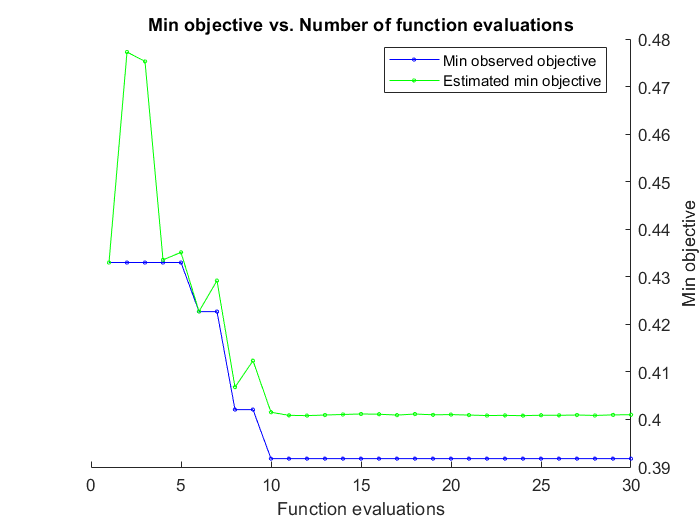

|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale | KernelFuncti-| PolynomialOr-|  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              | on           | der          |              |
|=================================================================================================================================================================|
|    1 | Best   |     0.43299 |      0.5091 |     0.43299 |     0.43299 |     onevsall |     0.091111 |            - |       linear |            - |        false |
|    2 | Accept |     0.52577 |     0.39616 |     0.43299 |     0.47726 |     onevsone |    0.0018751 |            - |       linear |            - |         true |
|    3 | Accept 

%% Train a classifier
% This code specifies all the classifier options and trains the classifier.
opts= struct('Optimizer', 'bayesopt', 'ShowPlots',true, 'AcquisitionFunctionName', 'expected-improvement-plus' );
Mdl = fitcecoc(...
    X, ...
    Y, 'Learners',t,...
    'Optimizehyperparameters', 'all',...
    'HyperparameterOptimizationOptions',opts,...
    'ClassNames', classOrder);

%CVSVMModel = crossval(Mdl)
%% Create the result struct with predict function

rng (1);
predictorExtractionFcn = @(x) array2table(x, 'VariableNames', predictorNames);
svmPredictFcn = @(x) predict(Mdl, x);
trainedClassifier.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.ClassificationSVM = Mdl;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2019a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new predictor column matrix, X, use: \n  yfit = c.predictFcn(X) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nX must contain exactly 373 columns because this model was trained using 373 predictors. \nX must contain only predictor columns in exactly the same order and format as your training \ndata. Do not include the response column or any columns you did not import into the app. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% Perform cross-validation
partitionedModel = crossval(Mdl, 'KFold', 10);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
validationAccuracy

validationAccuracy = 0.5876

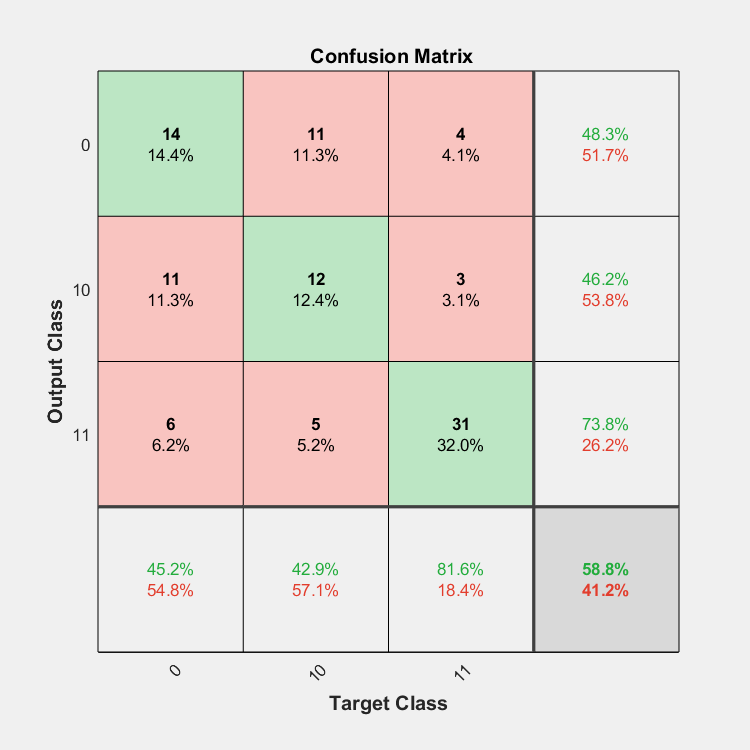

plotconfusion(Y, validationPredictions)

X = x';
Y = response;
classOrder = unique(Y);
rng (1); % For reproducibility
classOrder();

%% Train a classifier
% This code specifies all the classifier options and trains the classifier.

t = templateTree('MaxNumSplits', 20);
enMdl = fitcensemble(X,Y,'Method', 'RUSBoost', 'Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'));

%% crossval
crossv = crossval(enMdl, 'KFold', 10);

[ensValidationPredictions, ensValidationScores] = kfoldPredict(crossv);

%% loss
ensValidationAccuracy = 1 - kfoldLoss(crossv, 'LossFun', 'ClassifError');      
ensValidationAccuracy()

ans = 0.6186

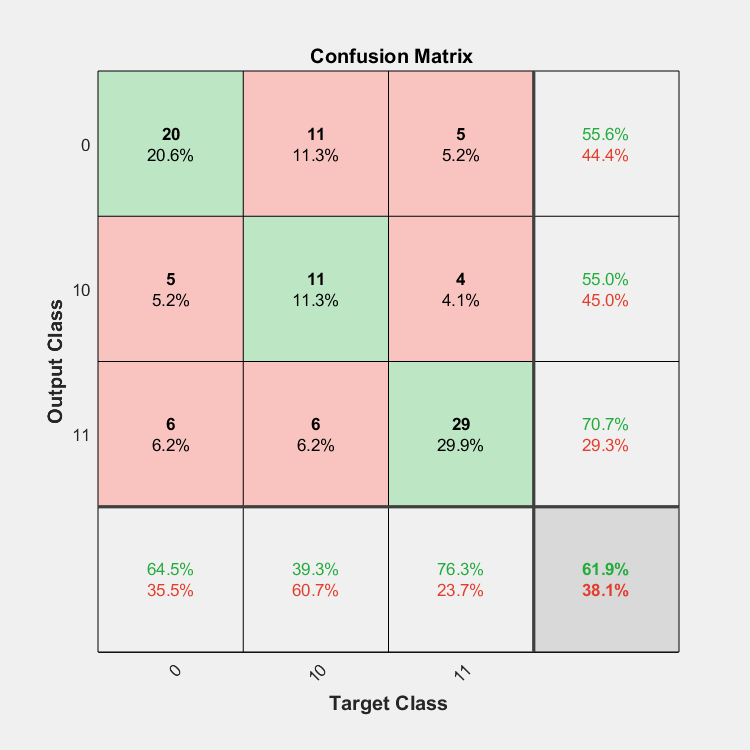

plotconfusion(Y, ensValidationPredictions)

tind = vec2ind(T);
yind = vec2ind(y);
% [confMat,order] = confusionmat(t,y);
% %%% calcul de la précision , le rappel (recall) et le F-score
% %%% recall
% for i =1:size(confMat,1)
%     recall(i)=confMat(i,i)/sum(confMat(i,:));
% end
% recall(isnan(recall))=[];
% *
% Recall*=sum(recall)/size(confMat,1);
% %%% précision
% for i =1:size(confMat,1)
%     precision(i)=confMat(i,i)/sum(confMat(:,i));
% end
% Precision=sum(precision)/size(confMat,1);
% %%% F-score
% F_score=2*Recall*Precision/(Precision+Recall); %%F_score=2*1/((1/Precision)+(1/Recall));
[c_matrix,Result,RefereceResult]= confusion.getMatrix(tind,yind)

Class List in given sample
     1
     2
     3


Total Instance = 97
class1==>1
class2==>2
class3==>3
Confusion Matrix
                     predict_class1    predict_class2    predict_class3
                     ______________    ______________    ______________

    Actual_class1          30                 0                 1      
    Actual_class2           3                25                 0      
    Actual_class3           1                 3                34      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive    FalseNegative    TrueNegative
                     ____________    _____________    _____________    ____________

    Actual_class

c_matrix =     30     0     1
     3    25     0
     1     3    34


Result = struct with fields:
                          Accuracy: 0.9175
                             Error: 0.0825
                       Sensitivity: 0.9184
                       Specificity: 0.9597
                         Precision: 0.9155
                 FalsePositiveRate: 0.0403
                          F1_score: 0.9158
    MatthewsCorrelationCoefficient: 0.8761
                             Kappa: 0.8144


RefereceResult = struct with fields:
                  AccuracyOfSingle: [3×1 double]
                     ErrorOfSingle: [3×1 double]
                   AccuracyInTotal: [3×1 double]
                      ErrorInTotal: [3×1 double]
                       Sensitivity: [3×1 double]
                       Specificity: [3×1 double]
                         Precision: [3×1 double]
                 FalsePositiveRate: [3×1 double]
                          F1_score: [3×1 double]
    MatthewsCorrelationCoefficient: [3×1 double]
                             Kappa: [3×1 double]
                      TruePositive: [3×1 double]
                     FalsePositive: [3×1 double]
                     FalseNegative: [3×1 double]
                      TrueNegative: [3×1 double]
                             Class: {3×1 cell}


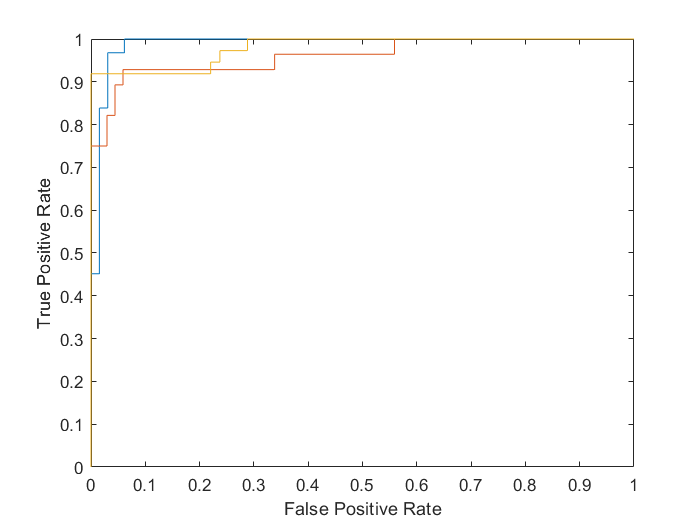

[Xclass1,Yclass1,Tclass1,AUCclass1] = perfcurve(T(1,:), y(1,:), 1);
[Xclass2,Yclass2,Tclass2,AUCclass2] = perfcurve(T(2,:), y(2,:), 1);
[Xclass3,Yclass3,Tclass3,AUCclass3] = perfcurve(T(3,:), y(3,:), 1);
plot(Xclass1,Yclass1)
hold on
plot(Xclass2,Yclass2)
hold on
plot(Xclass3,Yclass3)

xlabel('False Positive Rate'); ylabel('True Positive Rate')
%title(['ROC curve (AUC_Class1: ' num2str(AUCclass1); 'AUC_Class2: ' num2str(AUCclass2); 'AUC_Class3: ' num2str(AUCclass3) ')'])
hold off

% [Xlog,Ylog,Tlog,AUClog] = perfcurve(tind,yind,'true');
% plotroc(t,y)
%save